clear
time = 10;
sol_t = 0:0.1:time;
sol_size = size(sol_t,2);
node_number = 9;
x0 = [0; 3; 5; 8; 9; 11; 16; 18; 20];

plot_cons_wrap = @(L) plot_cons(L,x0,node_number,sol_size,sol_t);
calc_wrap = @(L) calc(L,x0,node_number,sol_size,sol_t);


% ex3.5
L5 = [1 -1 0 0 0 0 0 0 0;
     -1 3 -1 0 0 0 0 0 -1;
     0 -1 2 -1 0 0 0 0 0;
     0 0 -1 2 -1 0 0 0 0;
     0 0 0 -1 2 -1 0 0 0;
     0 0 0 0 -1 2 -1 0 0;
     0 0 0 0 0 -1 2 -1 0;
     0 0 0 0 0 0 -1 2 -1;
     0 -1 0 0 0 0 0 -1 2]; 
 eig(L5)

ans =    -0.0000
    0.4131
    0.5858
    1.1369
    2.0000
    2.3595
    3.4142
    3.6977
    4.3928


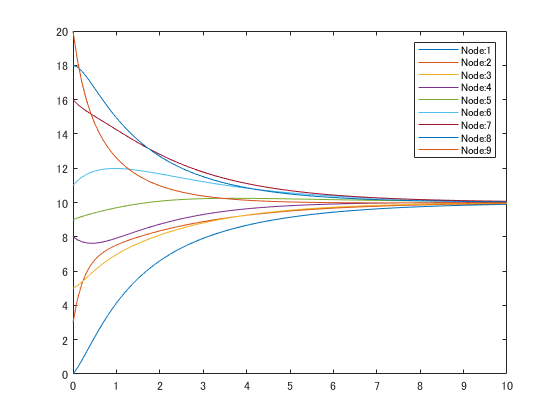

% x = calc_wrap(L5)
plot_cons_wrap(L5);

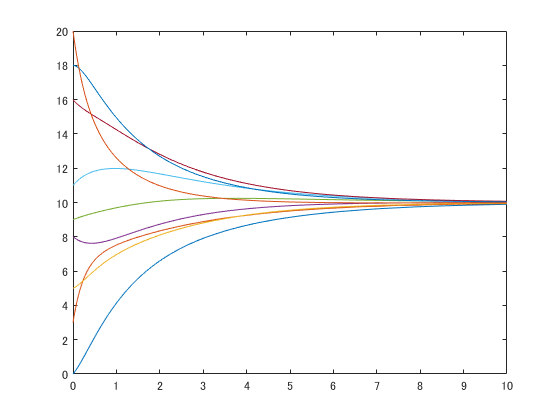

% over ode45

tspan = [0,time];
[t_ode,x_ode] = ode45(@(t,x) odesolver(t,x,L5), tspan, x0);
plot(t_ode,x_ode)

% ex3.6
D6 = [0 1 0 0 0 0 0 1 0;
     1 0 1 0 0 0 0 0 1;
     0 1 0 1 0 0 0 0 0;
     0 0 1 0 1 0 0 0 1;
     0 0 0 1 0 1 0 0 0;
     0 0 0 0 1 0 1 0 1;
     0 0 0 0 0 1 0 1 0;
     1 0 0 0 0 0 1 0 1;
     0 1 0 1 0 1 0 1 0];
 
L6 = graph_lap(D6)

L6 =      2    -1     0     0     0     0     0    -1     0
    -1     3    -1     0     0     0     0     0    -1
     0    -1     2    -1     0     0     0     0     0
     0     0    -1     3    -1     0     0     0    -1
     0     0     0    -1     2    -1     0     0     0
     0     0     0     0    -1     3    -1     0    -1
     0     0     0     0     0    -1     2    -1     0
    -1     0     0     0     0     0    -1     3    -1
     0    -1     0    -1     0    -1     0    -1     4


eig(L6)

ans =     0.0000
    1.0000
    1.0000
    2.0000
    3.0000
    3.0000
    4.0000
    4.0000
    6.0000


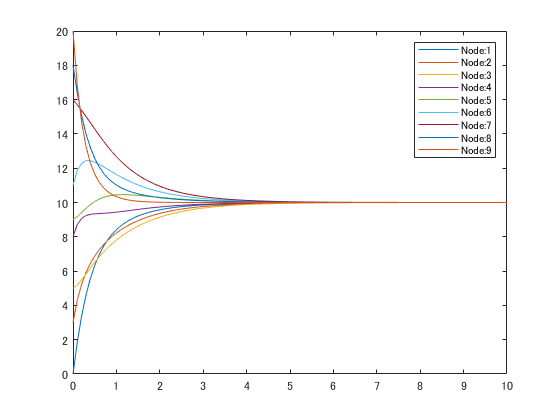

plot_cons_wrap(L6)

% ex3.7
D7 = [0 1 0 0 0 0 0 0 0;
     1 0 1 0 0 0 0 0 0;
     0 1 0 1 0 0 0 0 0;
     0 0 1 0 1 0 0 0 0;
     0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 1 0 1 0;
     0 0 0 0 0 0 1 0 1;
     0 0 0 0 0 0 0 1 0];
 
L7 = graph_lap(D7)

L =      1    -1     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0
     0     0     0    -1     1     0     0     0     0
     0     0     0     0     0     1    -1     0     0
     0     0     0     0     0    -1     2    -1     0
     0     0     0     0     0     0    -1     2    -1
     0     0     0     0     0     0     0    -1     1


eig(L7)
plot_cons_wrap(L7)

% 3.7 experiment for strange proof

D7 = [0 1 0 0 0 0 0 0 0;
     1 0 1 0 0 0 0 0 0;
     0 1 0 1 0 0 0 0 0;
     0 0 1 0 1 0 0 0 0;
     0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 1 0 1 0;
     0 0 0 0 0 0 1 0 1;
     0 0 0 0 0 0 0 1 0];
 
L7 = graph_lap(D7)

L7 =      1    -1     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0
     0     0     0    -1     1     0     0     0     0
     0     0     0     0     0     1    -1     0     0
     0     0     0     0     0    -1     2    -1     0
     0     0     0     0     0     0    -1     2    -1
     0     0     0     0     0     0     0    -1     1


[V,D] = eig(L7)

V =          0    0.4472   -0.6015         0    0.5117         0   -0.3717         0    0.1954
         0    0.4472   -0.3717         0   -0.1954         0    0.6015         0   -0.5117
         0    0.4472    0.0000         0   -0.6325         0   -0.0000         0    0.6325
         0    0.4472    0.3717         0   -0.1954         0   -0.6015         0   -0.5117
         0    0.4472    0.6015         0    0.5117         0    0.3717         0    0.1954
   -0.5000         0         0    0.6533         0    0.5000         0   -0.2706         0
   -0.5000         0         0    0.2706         0   -0.5000         0    0.6533         0
   -0.5000         0         0   -0.2706         0   -0.5000         0   -0.6533         0
   -0.5000         0         0   -0.6533         0    0.5000         0    0.2706         0


D =    -0.0000         0         0         0         0         0         0         0         0
         0   -0.0000         0         0         0         0         0         0         0
         0         0    0.3820         0         0         0         0         0         0
         0         0         0    0.5858         0         0         0         0         0
         0         0         0         0    1.3820         0         0         0         0
         0         0         0         0         0    2.0000         0         0         0
         0         0         0         0         0         0    2.6180         0         0
         0         0         0         0         0         0         0    3.4142         0
         0         0         0         0         0         0         0         0    3.6180


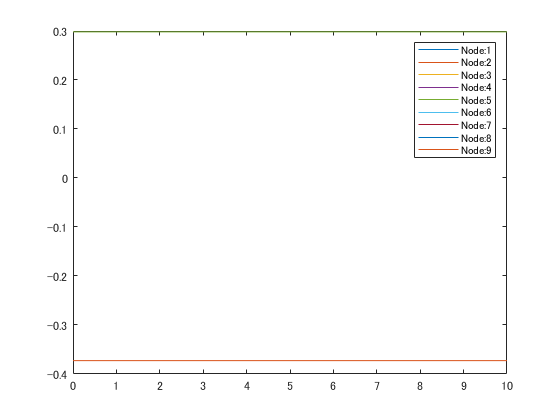

% p1 = [1;1;1;1;1;1;1;1;1]/3 ( = V(1)*(-1/0.5)+V(2)*(1/0.4472) ), so p2 can be
% p2=[4; 4; 4; 4; 4; -5; -5; -5; -5]/sqrt(180)
% under the condition p1・p2 = 0.
% in the textbook p.92, x0 is composed of p whose eigenvalue is 0 and whichi isn't p1.
% therefore, in this case, x0 can be set as p2.

x0 = [4; 4; 4; 4; 4; -5; -5; -5; -5]/sqrt(180); 

strngX = calc(L7,x0,node_number,sol_size,sol_t);
 
plot_cons(L7,x0,node_number,sol_size,sol_t);

% ex3.8
D11 = [0 0 0 0 0 0 0 1 0;
     1 0 0 0 0 0 0 0 1;
     0 1 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 1;
     0 0 0 1 0 0 0 0 0;
     0 0 0 0 1 0 0 0 1;
     0 0 0 0 0 1 0 0 0;
     0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 0 0 1 0];
L11 = graph_lap(D11)

L11 =      1     0     0     0     0     0     0    -1     0
    -1     2     0     0     0     0     0     0    -1
     0    -1     1     0     0     0     0     0     0
     0     0    -1     2     0     0     0     0    -1
     0     0     0    -1     1     0     0     0     0
     0     0     0     0    -1     2     0     0    -1
     0     0     0     0     0    -1     1     0     0
     0     0     0     0     0     0    -1     1     0
     0     0     0     0     0     0     0    -1     1


eig(L11)

ans =    2.6899 + 0.0000i
   2.1453 + 0.6508i
   2.1453 - 0.6508i
   1.3216 + 0.9951i
   1.3216 - 0.9951i
  -0.0000 + 0.0000i
   0.6882 + 0.7256i
   0.6882 - 0.7256i
   1.0000 + 0.0000i


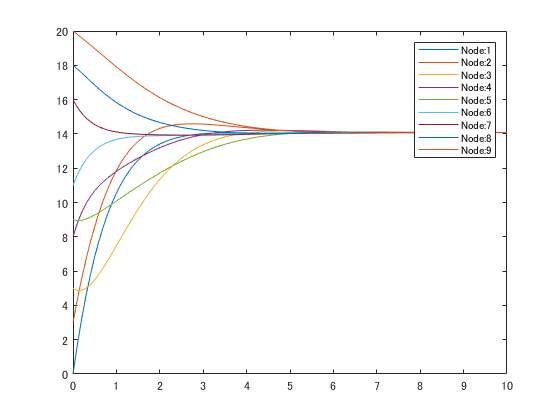

plot_cons_wrap(L11)

% ex3.9

D11 = [0 0 0 0 0 0 0 1 0;
     1 0 0 0 0 0 0 0 1;
     0 1 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0;
     0 0 0 1 0 0 0 0 0;
     0 0 0 0 1 0 0 0 1;
     0 0 0 0 0 1 0 0 0;
     0 0 0 0 0 0 1 0 1;
     0 1 0 0 0 1 0 1 0];
L11 = graph_lap(D11)

L11 =      1     0     0     0     0     0     0    -1     0
    -1     2     0     0     0     0     0     0    -1
     0    -1     1     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0
     0     0     0     0    -1     2     0     0    -1
     0     0     0     0     0    -1     1     0     0
     0     0     0     0     0     0    -1     2    -1
     0    -1     0     0     0    -1     0    -1     3


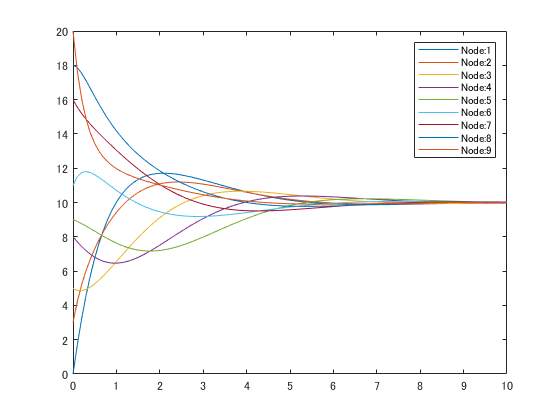

plot_cons_wrap(L11)

% ex3.10
D11 = [0 0 0 0 0 0 0 1 0;
     1 0 0 0 0 0 0 0 1;
     0 1 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 1;
     0 0 0 1 0 0 0 0 0;
     0 0 0 0 1 0 1 0 1;
     0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 0 0 1 0];
L11 = graph_lap(D11)

L11 =      1     0     0     0     0     0     0    -1     0
    -1     2     0     0     0     0     0     0    -1
     0    -1     1     0     0     0     0     0     0
     0     0    -1     2     0     0     0     0    -1
     0     0     0    -1     1     0     0     0     0
     0     0     0     0    -1     3    -1     0    -1
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     1     0
     0     0     0     0     0     0     0    -1     1


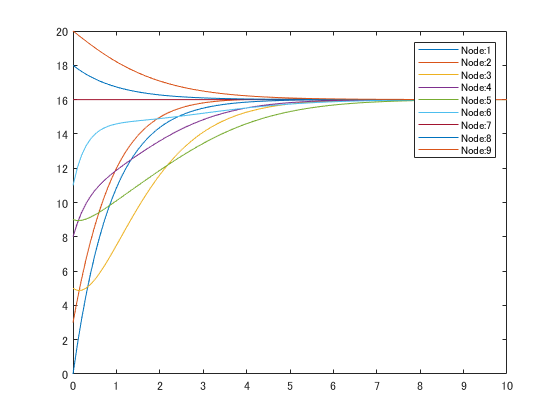

plot_cons_wrap(L11)

% ex3.11
D11 = [0 1 0 0 0 0 0 1 0;
     0 0 0 0 0 0 0 0 1;
     0 1 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0;
     0 0 0 1 0 0 0 0 0;
     0 0 0 0 1 0 1 0 1;
     0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 1;
     0 0 0 1 0 0 0 0 0];
L11 = graph_lap(D11)

L11 =      2    -1     0     0     0     0     0    -1     0
     0     1     0     0     0     0     0     0    -1
     0    -1     1     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0
     0     0     0     0    -1     3    -1     0    -1
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     2    -1
     0     0     0    -1     0     0     0     0     1


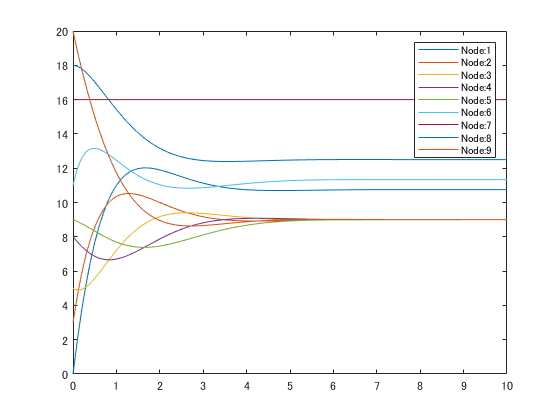

plot_cons_wrap(L11)